1. Present the mathematical explanation of eigenfaces, including how to generate the eigenfaces from the data set.

An eigenface is the measure of the variability between images in a larger set of images. In other words, its a measure of how close a face is to the average face of every face in the set of images. To generate the eigenfaces for the given data set first the images need to be converted into matricies. This can be done by reading the pgm images and converting them into double values, giving a 192x168 matrix for each face. To then calculate the mean face all the columns will be averaged and combined into one mean face matrix. Then mean centering the faces, by subtracting each column of each face in the set from this mean face, the new matricies is a measure of how each face differes from the mean face. Then by simply using singular value decomposition, the left singular vectors of each mean centered face is the eigenface.

The following code extracts the first 20 eigenfaces from the data set.

2. Implement code in MATLAB to produce the mean face and eigenfaces figures from the Background Reading document.

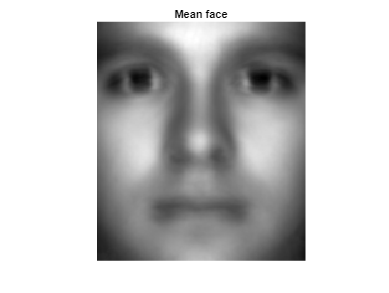

% setting the basic
I_d = zeros(32256,1000);

d = dir('faces/*.pgm');
for i = 1:length(d)
    % load in 192x168 matrix representing face
    I(:, :, i) = imread(['faces/', d(i).name]);

    % convert from uint8 to double and reformat the image into a left hand
    % side vector to then add to a group photo matrix
    vec = reshape(double(I(:, :, i)),[],1);
    I_d(:,i) = vec;
end

% calculating the mean face
V_m = mean(I_d, 2);

M_mean = zeros(32256,1000);
for i = 1:1000
    % subtract the mean face from all photos
    M_mean(:, i) = I_d(:, i) - V_m;
end

% calculating our eigenfaces (the U matrix)
[U,Sigma,V] = svd(M_mean, 'econ');

% turning the mean face we calculated from a vector to a matrix
Mean_face = zeros(192,168);
for i = 1:168
    Mean_face(:,i) = V_m(192*(i-1)+1:192*(i-1)+192);
end

% displaying the Mean Face
figure(1)
imshow(Mean_face, 'initialmagnification', 'fit', 'DisplayRange', [])
title('Mean face')

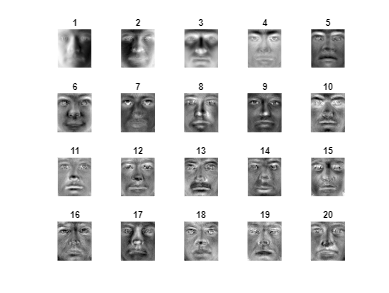


% displaying the first 20 eigenfaces Eigen Faces
figure(2)
for i = 1:20
    Eigen_face = zeros(192,168);
    for j = 1:168
        Eigen_face(:,j) = U(192*(j-1)+1:192*(j-1)+192,i);
    end
    subplot(4, 5, i)
    imshow(Eigen_face, 'initialmagnification', 'fit', 'DisplayRange', [])
    title((i))
end

3. Present the mathematical explanation of how to represent an image by its projection onto v-dimensional "eigenface space", including calculating its coordinate vector.

Seeing as the singular values in Sigma decay rapidly, meaning there is little variance between eigen faces, using linear combinations of the first v eigenfaces, where v<N, a good reconstruction of each face in the data set can be achieved. This means that each face would correspond to a v-dimensional coordinate vector and in turn, be its projection onto the "eigenface space".

4.

% setting up the projection matrix for our function
proj_matrix = U(:,1:20)

proj_matrix =     0.0047   -0.0063   -0.0008   -0.0030   -0.0074    0.0077    0.0020   -0.0010   -0.0099    0.0024   -0.0019    0.0029   -0.0035   -0.0023   -0.0002   -0.0048   -0.0044   -0.0044    0.0006    0.0049
    0.0048   -0.0064   -0.0008   -0.0029   -0.0075    0.0078    0.0016   -0.0006   -0.0097    0.0023   -0.0011    0.0025   -0.0042   -0.0031   -0.0004   -0.0043   -0.0045   -0.0043    0.0002    0.0056
    0.0048   -0.0063   -0.0009   -0.0031   -0.0077    0.0076    0.0015   -0.0002   -0.0091    0.0024   -0.0001    0.0027   -0.0048   -0.0030   -0.0009   -0.0033   -0.0044   -0.0041   -0.0007    0.0067
    0.0048   -0.0063   -0.0010   -0.0034   -0.0081    0.0070    0.0015   -0.0004   -0.0086    0.0025    0.0010    0.0029   -0.0059   -0.0030   -0.0012   -0.0024   -0.0039   -0.0039   -0.0015    0.0070
    0.0048   -0.0062   -0.0011   -0.0036   -0.0080    0.0062    0.0013   -0.0006   -0.0084    0.0029    0.0017    0.0028   -0.0066   -0.0027   -0.0012   -0.0017   -0.0037   -0.0037  


% guy with a mustache correctly identified
mustache(I_d(:,555), proj_matrix) 

ans = 'yes'

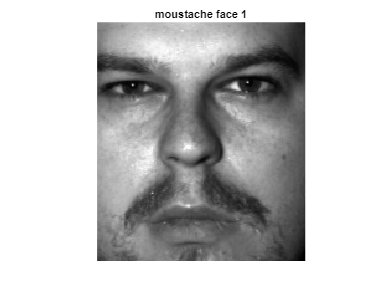

figure(3)
imshow(I(:,:,555), 'initialmagnification', 'fit', 'DisplayRange', [])
title('moustache face 1')


% guy with a mustache incorrectly identified
mustache(I_d(:,557), proj_matrix) 

ans = 'no'

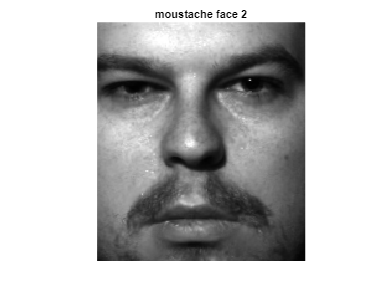

figure(4)
imshow(I(:,:,557), 'initialmagnification', 'fit', 'DisplayRange', [])
title('moustache face 2')


% guy without a mustache correctly identified
mustache(I_d(:,1000), proj_matrix) 

ans = 'no'

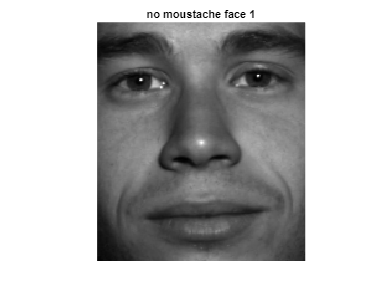

figure(5)
imshow(I(:,:,1000), 'initialmagnification', 'fit', 'DisplayRange', [])
title('no moustache face 1')


% guy without a mustache incorrectly identified
mustache(I_d(:,999), proj_matrix) 

ans = 'yes'

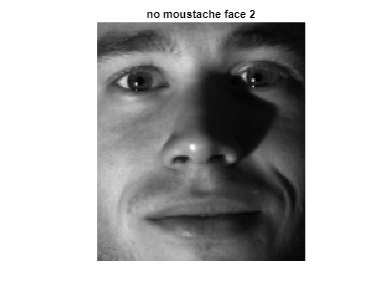

figure(6)
imshow(I(:,:,999), 'initialmagnification', 'fit', 'DisplayRange', [])
title('no moustache face 2')


% the function
function ans = mustache(face,A)
    ATA = A' * A;
    ATB = A' * face;
    R = rref([ATA ATB]);
    x = R(:, end);
    M = 0.06;
    F13 = x(13,1);
    if abs(F13)/abs(sum(x))>M
        ans = 'yes';
    else
        ans = 'no';
    end
end